7.7  （两个简单示例）实时脚本

由张志涌编写、修改于 2023.1。

单行解题命令

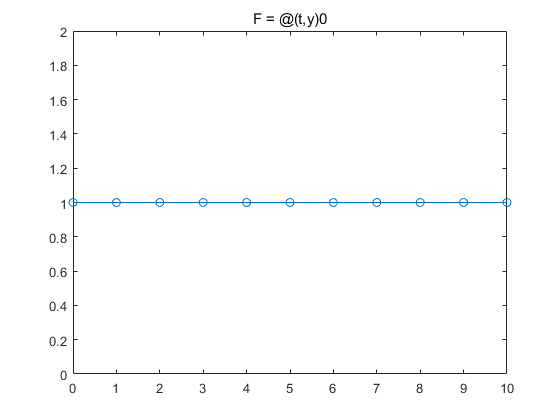

F = @(t,y) 0 ; ode23tx(F,[0 10],1);title('F = @(t,y)0')

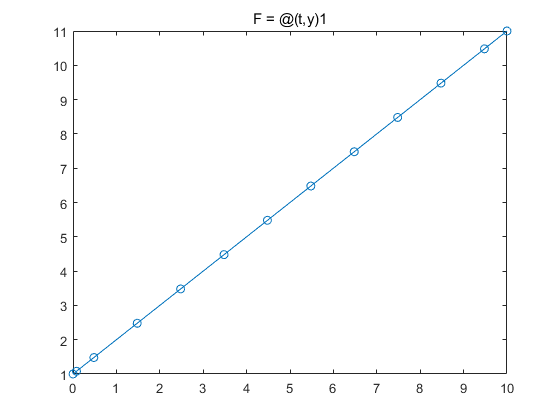

F = @(t,y) 1 ; ode23tx(F,[0 10],1);title('F = @(t,y)1')

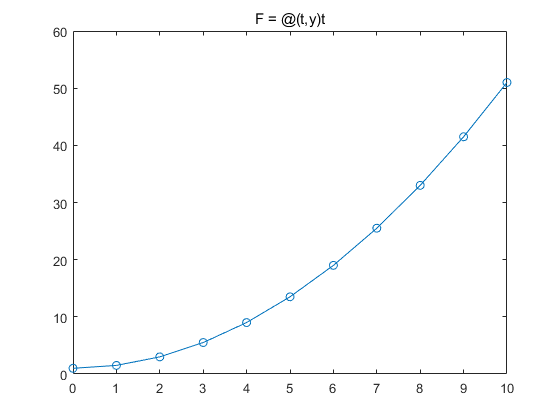

F = @(t,y) t ; ode23tx(F,[0 10],1);title('F = @(t,y)t')

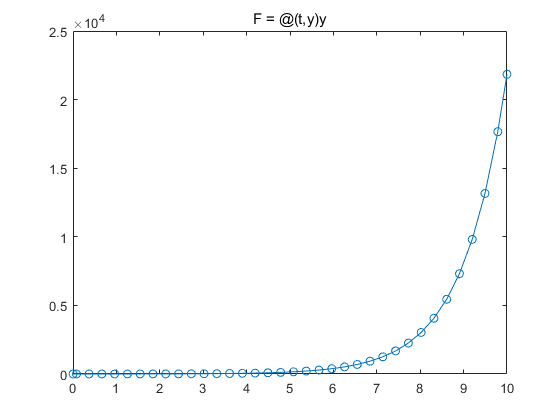

F = @(t,y) y ; ode23tx(F,[0 10],1);title('F = @(t,y)y')

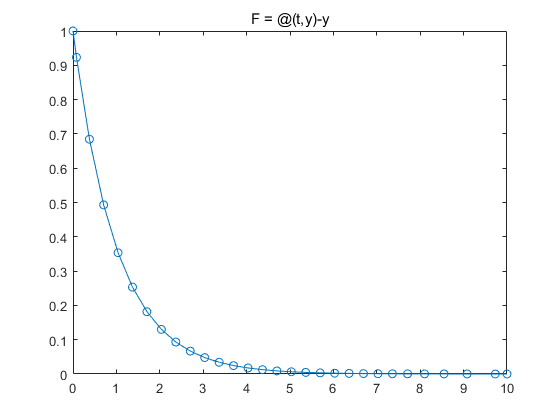

F = @(t,y) -y ; ode23tx(F,[0 10],1);title('F = @(t,y)-y')

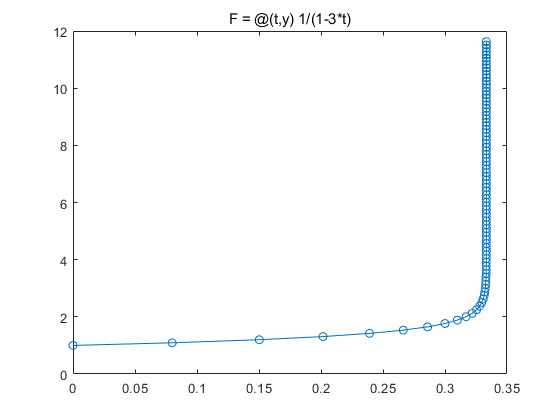

F = @(t,y) 1/(1-3*t) ; ode23tx(F,[0 10],1);title('F = @(t,y) 1/(1-3*t)')

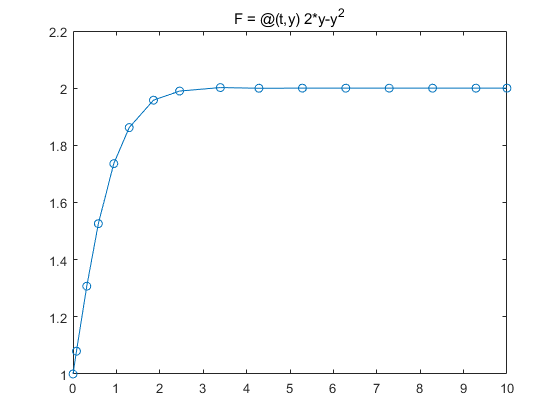

F = @(t,y) 2*y-y^2 ; ode23tx(F,[0 10],1);title('F = @(t,y) 2*y-y^2')

`谐波振荡器`

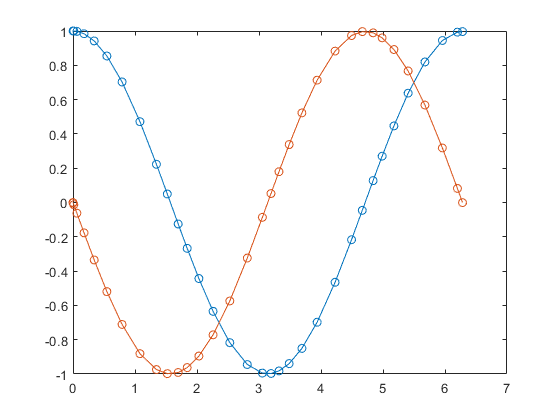

F = @(t,y) [y(2); -y(1)];
ode23tx(F,[0 2*pi],[1; 0])

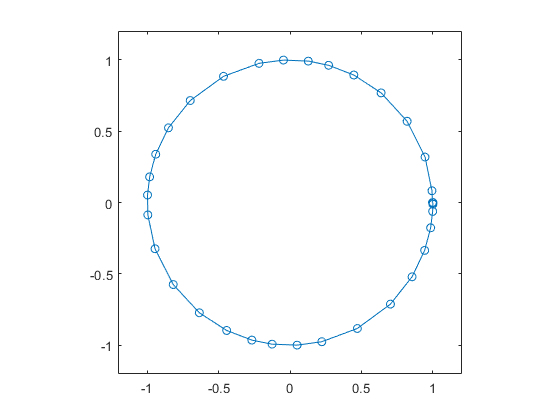

[t,y] = ode23tx(F,[0 2*pi],[1; 0]);
plot(y(:,1),y(:,2),'-o')
axis([-1.2 1.2 -1.2 1.2])
axis square

边算边画

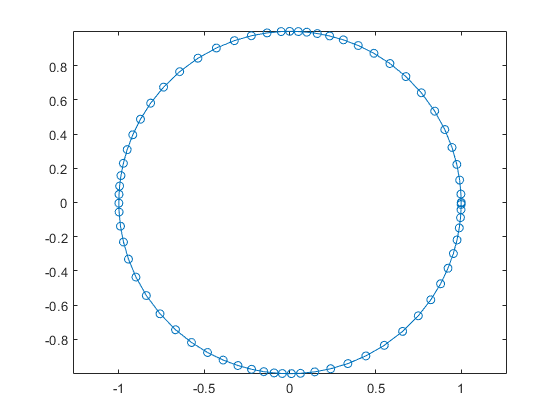

close all
opts = odeset('reltol',1.e-4,'abstol',1.e-6, ...
'outputfcn',@odephas2);
ode23tx(F,[0 2*pi],[1; 0],opts)
axis equal

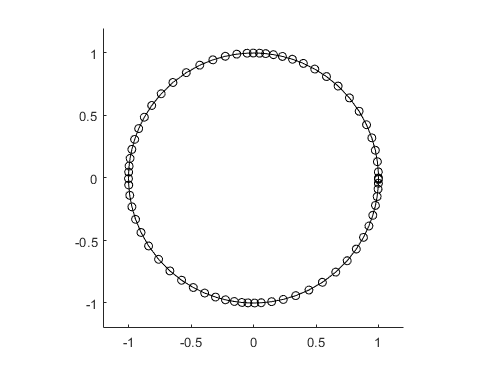

close all
opts = odeset('reltol',1.e-4,'abstol',1.e-6, ...
'outputfcn',@phaseplot);
ode23tx(F,[0 2*pi],[1; 0],opts)

双体问题

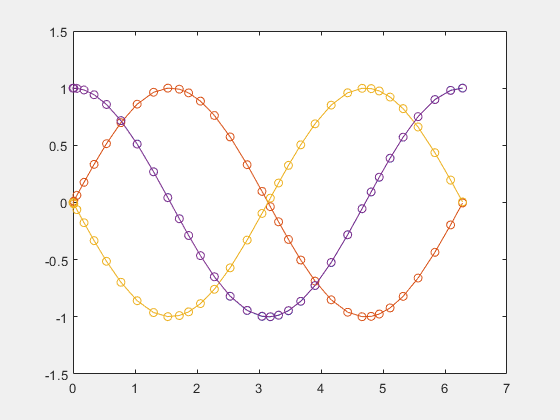

figure
ode23tx(@twobody,[0 2*pi],[1; 0; 0; 1]);

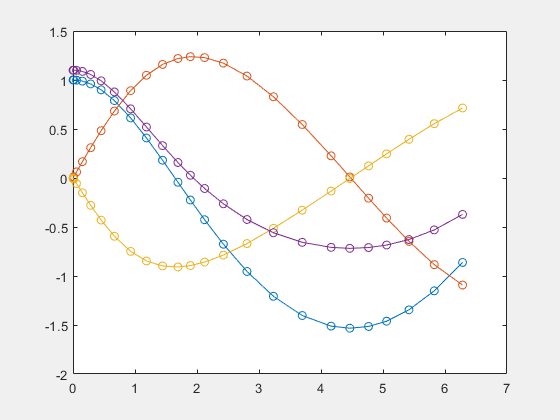

change_this=1.1;
y0 = [1; 0; 0; change_this];
ode23tx(@twobody,[0 2*pi],y0);

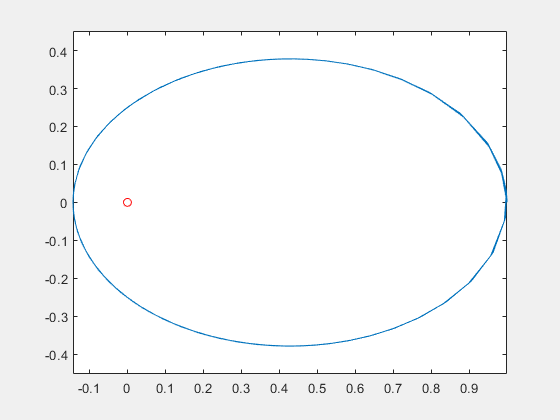

change_this=0.5;
y0 = [1; 0; 0; change_this];
[t,y] = ode23tx(@twobody,[0 2*pi],y0);
plot(y(:,1),y(:,2),'-',0,0,'ro')
axis equal

function flag = phaseplot(t,y,job)
persistent p
    if isequal(job,'init')
        p=animatedline(y(1),y(2),'Marker','o');
        axis([-1.2 1.2 -1.2 1.2])
        axis square
        flag = 0;
    elseif isequal(job,'')
        addpoints(p,y(1),y(2))
        pause(0.2)
        flag = 0;
    end
end